LOAD_IMAGES

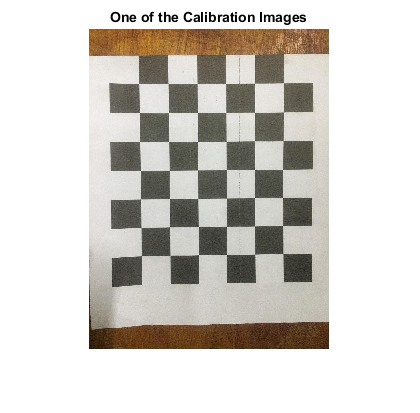

%display all images
numImages = 30;
files = cell(1, numImages);
for i = 1:numImages
    files{i} = sprintf('suli_%d.jpg', i);
end

% Display one of the calibration images
magnification = 25;
I = imread(files{1});
figure; imshow(I, 'InitialMagnification', magnification);
title('One of the Calibration Images');

**Estimate Camera Parameters**

% Determine the corners of the chesckerboard
[imagePoints, boardSize] = detectCheckerboardPoints(files);

% Extract  the WC  of the checkerboard corners in the
% pattern-centric coordinate system, with the upper-left corner at (0,0).
squareSize = 25; %  square size in millimeters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera.
imageSize = [size(I, 1), size(I, 2)];
cameraParams = estimateCameraParameters(imagePoints, worldPoints, ...
                                     'ImageSize', imageSize)

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                   RotationMatrices: [3×3×29 double]
                 TranslationVectors: [29×3 double]

   Accuracy of Estimation
              MeanReprojectionError: 0.4617
                 ReprojectionErrors: [42×2×29 double]
                  ReprojectedPoints: [42×2×29 double]

   Calibration Settings
                        NumPatterns: 29
                        WorldPoints: [42×2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


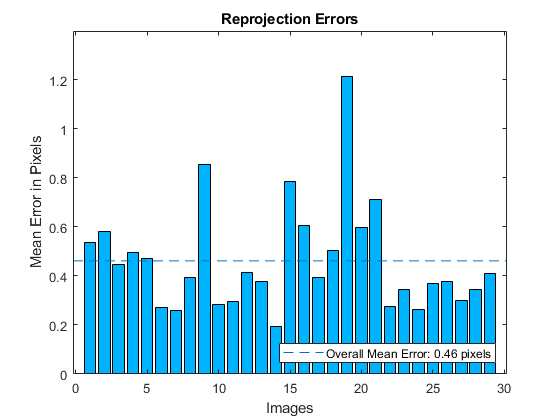


% Evaluate calibration accuracy.
figure; showReprojectionErrors(cameraParams);
title('Reprojection Errors');

**Read the Image of Objects to Be Measured**

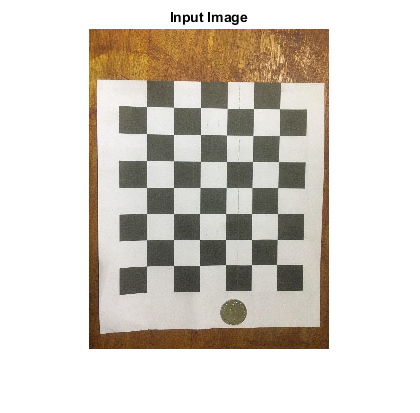

imOrig = imread('suli_8.jpg'); % image which contains object
figure; imshow(imOrig, 'InitialMagnification', magnification);
title('Input Image');

**Undistort the Image**

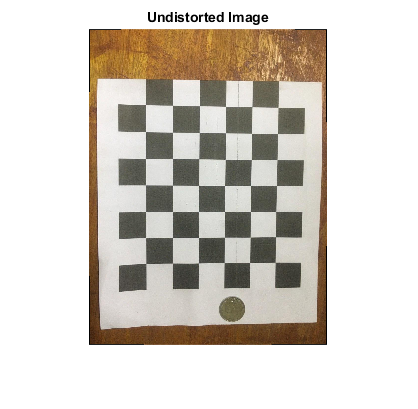

%The lens has introduced so little distortion, I use the "full" output view to illustrate this
% The image is not distorted. 
% If  used the default "same" option, that would be difficult
% To notice any difference when compared to the original image. Notice the small black borders.
[im, newOrigin] = undistortImage(imOrig, cameraParams, 'OutputView', 'full');
figure; imshow(im, 'InitialMagnification', magnification);
title('Undistorted Image');

**Segment Coin**

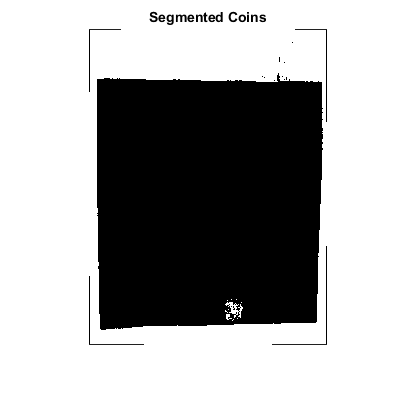

% Convert image to the "HSV" color space.
imHSV = rgb2hsv(im);

% Get the saturation channel.
saturation = imHSV(:, :, 2);

% Threshold the image
t = graythresh(saturation);
imCoin = (saturation > t);

figure; imshow(imCoin, 'InitialMagnification', magnification);
title('Segmented Coins');

**Detect Coin**

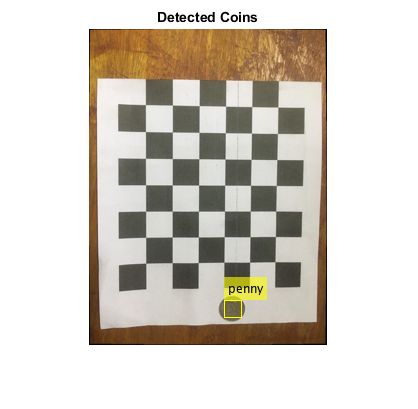

% Find connected components.
blobAnalysis = vision.BlobAnalysis('AreaOutputPort', true,...
    'CentroidOutputPort', false,...
    'BoundingBoxOutputPort', true,...
    'MinimumBlobArea', 200, 'ExcludeBorderBlobs', true);
[areas, boxes] = step(blobAnalysis, imCoin);

% Sort connected components in descending order by area
[~, idx] = sort(areas, 'Descend');

% Get the two largest components.
boxes = double(boxes(idx(1), :)); %change the quantity

% Reduce the size of the image for display.
scale = magnification / 100;
imDetectedCoins = imresize(im, scale);

% Insert labels for the coins.
imDetectedCoins = insertObjectAnnotation(imDetectedCoins, 'rectangle', ...
    scale * boxes, 'penny');
figure; imshow(imDetectedCoins);
title('Detected Coins');

**Compute Extrinsics**

% Detect the checkerboard.
[imagePoints, boardSize] = detectCheckerboardPoints(im);

% Adjust the imagePoints so that they are expressed in the coordinate system
% used in the original image, before it was undistorted.  This adjustment
% makes it compatible with the cameraParameters object computed for the original image.
imagePoints = imagePoints + newOrigin; % adds newOrigin to every row of imagePoints

% Compute rotation and translation of the camera.
[R, t] = extrinsics(imagePoints, worldPoints, cameraParams);

**Measure the  Coin**

% Adjust upper left corners of bounding boxes for coordinate system shift 
% caused by undistortImage with output view of 'full'. This would not be
% needed if the output was 'same'. The adjustment makes the points compatible
% with the cameraParameters of the original image.
boxes = boxes + [newOrigin, 0, 0]; % zero padding is added for widht and height

% Get the top-left and the top-right corners.
box1 = double(boxes(1, :));
imagePoints1 = [box1(1:2); ...
                box1(1) + box1(3), box1(2)];

% Get the world coordinates of the corners            
worldPoints1 = pointsToWorld(cameraParams, R, t, imagePoints1);

% Compute the diameter of the coin in millimeters.
d = worldPoints1(2, :) - worldPoints1(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf('Measured diameter of the coin = %0.2f mm\n', diameterInMillimeters);

Measured diameter of the coin = 17.44 mm


**Measure the Distance to The  Coin**

% Compute the center of the first coin in the image.
center1_image = box1(1:2) + box1(3:4)/2;

% Convert to WC.
center1_world  = pointsToWorld(cameraParams, R, t, center1_image);

% Add the 0 z-coordinate.
center1_world = [center1_world 0];

% Compute the distance from the camera to the coin .
[~, cameraLocation] = extrinsicsToCameraPose(R, t);
distanceToCamera = norm(center1_world - cameraLocation);
fprintf('Distance from the camera to the  coin = %0.2f mm\n', ...
    distanceToCamera);

Distance from the camera to the  coin = 302.16 mm
